# Pattern Nulling Lab

Sometimes it may be desirable to reduce the antenna pattern in a certain direction. For example, if there is a known emitter in that direction that is interfering with the systems ability to monitor a desired signal.

In this lab, we look at a simple approach for inserting a null into the antenna pattern in a certain direction.

## Setup

First, put the HB100 transmitter as close to boresight as possible.

Run the following to clear the workspace.

clear;
close all;
warning('off','MATLAB:system:ObsoleteSystemObjectMixin');

We also load the calibration weights which are applied so that the beam pattern matches our expectations.

load('CalibrationWeights.mat','calibrationweights');

### Identify HB100 Frequency

Before collecting any data, we need to identify the operating frequency of the HB100. Run the following script to do so.

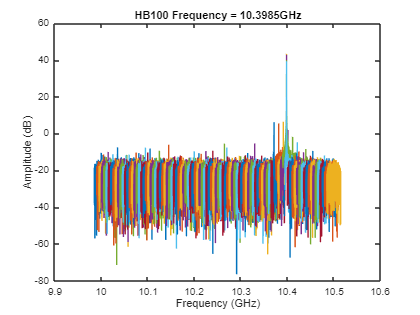

fc_hb100 = findTxFrequency();

### Create Antenna Interactor

The antenna interactor object helps us to interact with the phaser board to steer the beam and collect data. Create this object so that we can control the antenna.

ai = AntennaInteractor(fc_hb100,calibrationweights);

### Create Antenna Model

In order to generate amplitudes and phases to change the antenna pattern behavior, we need to have an approximate model of the antenna array. The Phaser antenna array is made up of two four-element uniform linear arrays (ULA). The antenna element spacing is 1/2 wavelength at a frequency of 10.39875 GHz. We create this antenna model below.

lambda = freq2wavelen(10.39875e9);
spacing = lambda/2;
array = phased.ULA(NumElements=8,ElementSpacing=spacing);
elementLocation = array.getElementPosition();

## Pattern Nulling demonstration

In this lab, we first locate the transmitter azimuth. We then collect the signal magnitude with and without pattern nulling when a null is inserted in the direction of the transmitter.

Try moving the transmitter to different locations and rerunning the following sections to see that the nulling can be steered in different directions.

### Find Transmitter

First, collect the antenna pattern to locate the position of the transmitter. Measure a few times and take the mean for a more accurate prediction.

steerangles = -90:0.5:90;
nCaptures = 5;
patternMag = zeros(nCaptures,length(steerangles));
for i = 1:nCaptures
    patternData = ai.capturePattern(steerangles);
    mag = helperGetAmplitude(patternData);
    patternMag(i,:) = mag / max(mag);
end
meanpat = mean(patternMag,1);
[~,txidx] = max(meanpat);
txAngle = steerangles(txidx);

### Collect Pattern With and Without Null

With the transmitter location known, we plot the magnitude of the collected signal while steering the beam so that the transmitter is in the first sidelobe of the antenna pattern which occurs around 22 degrees. We collect the signal magnitude with and without nulling to see the impact that nulling has on the collected signal magnitude.

firstSidelobe = 22;
nullAngle = txAngle;
steerAngle = txAngle + firstSidelobe;

We capture the collected magnitude with and without nulling applied for multiple time steps and plot the difference. In order to insert a null, we substract the null weights from the steering weights.

nSteps = 20;
magWithoutNull = zeros(nSteps,1);
magWithNull = zeros(nSteps,1);
for i = 1:nSteps
    % Get the steering vector that directs the beam in the desired
    % direction
    steerweights = steervec(elementLocation/freq2wavelen(fc_hb100),[steerAngle;0]);

    % Get the steering vector for the null direction
    nullweights = steervec(elementLocation/freq2wavelen(fc_hb100),[nullAngle;0]);

    % Calculate the null steering weights
    rn = sum(diag(nullweights'*steerweights))/sum(diag((nullweights'*nullweights)));
    nullsteer = steerweights-nullweights.*rn;

    % Get the signal magnitude without nulling
    steerweights = analogWeightsCalAdjustment([steerweights(1:4) steerweights(5:8)],calibrationweights.AnalogWeights);
    data = ai.steerAnalog(steerweights);
    digitalsteer = digitalWeightsCalAdjustment([1;1],calibrationweights.DigitalWeights);
    data = data * conj(digitalsteer);
    magWithoutNull(i) = mag2db(helperGetAmplitude(data));

    % Get the signal magnitude with nulling
    nullsteer = analogWeightsCalAdjustment([nullsteer(1:4) nullsteer(5:8)],calibrationweights.AnalogWeights);
    data = ai.steerAnalog(nullsteer);
    digitalsteer = digitalWeightsCalAdjustment([1;1],calibrationweights.DigitalWeights);
    data = data * conj(digitalsteer);
    magWithNull(i) = mag2db(helperGetAmplitude(data));
end

### Plot Collected Data

Now that we have collected the magnitude of the returned signal with and without nulling, we compare the two. We can see that by inserting a null, we reduce the captured signal magnitude.

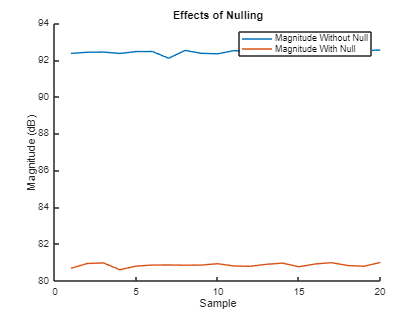

% Plot the antenna pattern
ax = axes(figure);
hold(ax,"on");
plot(ax,magWithoutNull,DisplayName="Magnitude Without Null");
plot(ax,magWithNull,DisplayName="Magnitude With Null");
title(ax,'Effects of Nulling');
xlabel(ax,'Sample');
ylabel(ax,'Magnitude (dB)');
legend(ax);